

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice7'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = '7_2_a.in'; % Nom du fichier d'entree de base

cb_gauche = 'pulse';
cb_droit = 'fixe';

output = ['7_2_a',cb_gauche,cb_droit];
cmd = sprintf('wsl %s%s %s cb_gauche=%s cb_droit=%s  output=%s tfin=%.15g', repertoire, executable, input, cb_gauche,cb_droit,output,14);
disp(cmd);

wsl ./Exercice7 7_2_a.in cb_gauche=pulse cb_droit=fixe  output=7_2_apulsefixe tfin=14


system(cmd);

	tfin=14
	L=20
	Npoints=500
	CFL=0.9
	type_u2=const
	u=6
0.0400802
0.00601202
	ecrire_f=1
	schema=A
	cb_gauche=pulse
	cb_droit=fixe
	A=1
	omega=5
	output=7_2_apulsefixe
	n_stride=10


fichier = output;
data = load([fichier,'_u.out']);
x = data(:,1);
u = data(:,2);
data = load([fichier,'_E.out']);
t = data(:,1);
E = data(:,2);
data = load([fichier,'_f.out']);
f = data(:,2:end);

%% Figures %%
%%%%%%%%%%%%%



% [X, T]=meshgrid(x,t);
% X = (reshape(X,1,[]))';
% T = (reshape(T,1,[]))';
% F= (reshape(f,1,[]))';
% d = [X T F];
% 
% save([output '.dat'],'d','-ascii');

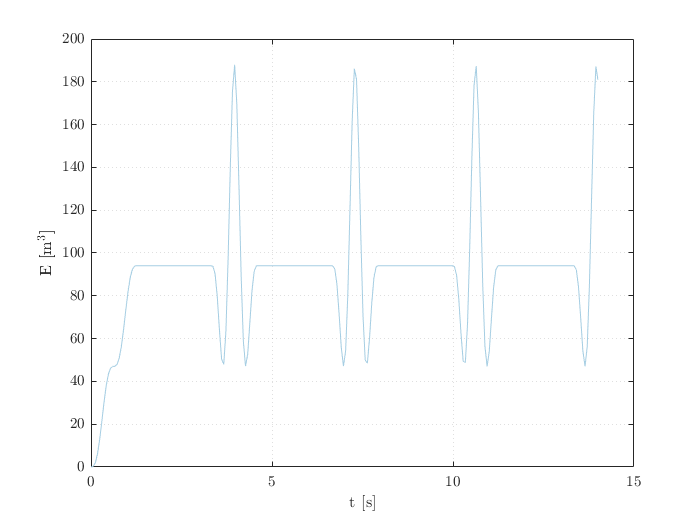



figure
plot(t,E)
grid
xlabel('t [s]')
ylabel('E [m$^3$]')



fheat = figure

fheat =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [584 630 560 420]
       Units: 'pixels'

  Show all properties





H = 5;
W = 8;
fheat.PaperUnits='centimeters';
fheat.InvertHardcopy='on';
fheat.PaperSize=[W H];
fheat.PaperPosition=[0 0 W H];
ax = axes(fheat,'Box','off');

pcolor(x,t,f)
shading interp
colormap jet


c = colorbar;
c.Label.Interpreter= 'latex'

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-1.9996 1.9973]
    FontSize: 8.1000
    Position: [0.8298 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


c.TickLabelInterpreter = 'latex'

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-1.9996 1.9973]
    FontSize: 8.1000
    Position: [0.8298 0.1105 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


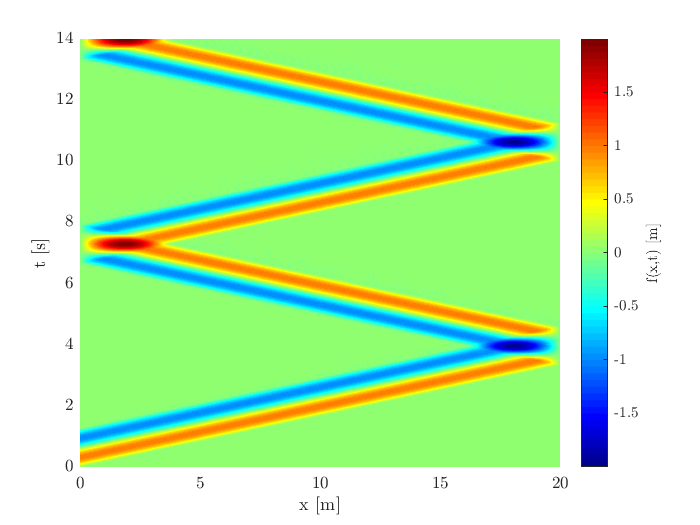

xlabel('x [m]')
ylabel('t [s]')
ylabel(c,'f(x,t) [m]')

print(fheat,[output 'heat'],'-depsc2','-r300')